clear;
%{
n = 17;
rng(n, "philox");
M = randi([100000 1000000]) / 1000 / sqrt(2)
m = randi([1000 10000]) / 1000 * sqrt(3)
l = randi([100 1000]) / sqrt(5) / 100
%}

M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];

beta = 10

beta = 10

cvx_begin sdp
variable Q(4, 4)
variable Y(4, 2)
Q>0.0001*eye(4);

A'*Q+Q*A+2*beta*Q + C'*Y' + Y*C <= 0;


cvx_end

 
Calling SDPT3 4.0: 26 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of sdp    var  =  8,   num. of sdp  blk  =  2
 dim. of free   var  =  6 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.0e+02|6.2e+01|3.0e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.951|0.984|1.5e+01|1.1e+00|4.3e+01| 0.000000e+00  4.458568e-03| 0:0:00| chol  1  1 
 2|1.000|0.831|1.0e-06|2.0e-01|2.7e+00| 0.000000e+00  4.458919e-03| 0:0:00| chol  1  1 
 3|1.000|0.991|1.0e-03|2.6e-03|3.2e-02| 0.000000e+00  5.379967e-05| 0:0:00| 


L=pinv(Q)*Y

L =   -45.5642   -0.0211
 -706.4272   -0.5932
   -0.0140  -45.6416
   -0.3128 -711.8063



alpha = 0.005

alpha = 0.0050


cvx_begin sdp

variable P(4, 4)
variable Y1(1, 4)
P > 0.000001 * eye(4);

P*A'+A*P + 2*alpha*P + Y1'*B' +B*Y1 <= 0;


cvx_end

 
Calling SDPT3 4.0: 24 variables, 11 equality constraints
------------------------------------------------------------

 num. of constraints = 11
 dim. of sdp    var  =  8,   num. of sdp  blk  =  2
 dim. of free   var  =  4 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.2e+01|3.6e+01|1.3e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.887|0.890|8.1e+00|4.1e+00|1.0e+02| 0.000000e+00  1.891134e-05| 0:0:00| chol  1  1 
 2|0.867|0.797|1.1e+00|8.4e-01|2.0e+01| 0.000000e+00  1.831584e-05| 0:0:00| chol  1  1 
 3|0.800|0.465|2.2e-01|4.5e-01|1.1e+01| 0.000000e+00  1.992618e-05| 0:0:00|

K = Y1 *pinv(P)

K = 1.0e+03 *

    0.0108    0.1270   -4.5673   -1.8946


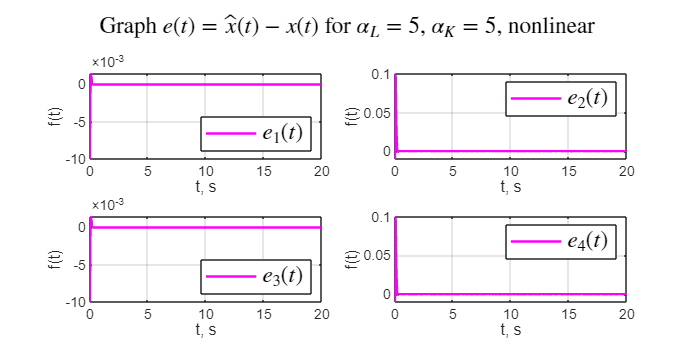


%[V_A eig_A] = eig(A);
%{
U_A = [B A*B A^2*B A^3*B];
ru = rank(U_A);
V_A = [C; C*A; C*A^2; C*A^3];
rv = rank(V_A);

sys_uy = ss(A, B, C, 0); % Создание системы (D=0 для W_uy)
sys_fy = ss(A, D, C, 0);  % Создание системы (B=0 для W_fy)

% Передаточные функции
W_uy = tf(sys_uy);
W_fy = tf(sys_fy);
zero(W_uy(1));
zero(W_uy(2));
zero(W_fy(1));
zero(W_fy(2));

pole(W_uy(1));
pole(W_uy(2));
pole(W_fy(1));
pole(W_fy(2));
%}

%{
Gamma_r = [-3 0 0 0; 0 -2.5 0 0; 0 0 -2 0; 0 0 0 -1.5];
Y_r = [1 1 1 1];

cvx_begin sdp

variable P_r(4, 4)
A*P_r-P_r*Gamma_r == B*Y_r;

cvx_end
A*P_r;
P_r;
det(P_r);
K = -Y_r*pinv(P_r)

eig(A+B*K)

% Наблюдатель полной размерности (модальный)
Gamma_obs = [-1 0 0 0; 0 -2 0 0; 0 0 -3 0; 0 0 0 -4];
Y_obs = [1 1; 1 1; 1 1; 1 1];

cvx_begin sdp

variable Q_obs(4, 4);
Gamma_obs*Q_obs-Q_obs*A==Y_obs*C;
cvx_end

Q_obs;
det(Q_obs);
L = pinv(Q_obs)*Y_obs;

eig(A+L*C);
U_obs = [Y_obs Gamma_obs*Y_obs Gamma_obs^2*Y_obs Gamma_obs^3*Y_obs];
ru_obs = rank(U_obs);
%}


x_00 = [0; 0; 0; 0];
x_02 = [0.01; 0.01; 0.05; 0.01];
x_03 = [0.05; 0.01; 0.01;0.01];
x_04 = [0.01; 0.01; 0.01; 0.05]; % это x1
x_044 = [0.01; 0.01; pi/60; 0.01];
x_05 = [0.01; 0.01; 0.01; 0.05];
x_06 = [0.01; 0.1; 0.01; 0.01];
x_07 = [0.01; 0.01; 0.01; 0.01];
x_0 = x_07;
x_0_h = x_00;
%u = 0;    % Управляющая сила (Н)
f = 0;
%{
% Временной интервал
tspan = [0 7];

%наблюдатель пониженной размерности

Gamma_o2 = [-1 0; 0 -1.5]
Yo2 = [1 1;1 1]
%Uo2 = [Yo2 Gamma_o2*Yo2];
%det(Uo2)

cvx_begin sdp

variable Q_o2(2, 4);

Gamma_o2*Q_o2-Q_o2*A==Yo2*C;
cvx_end

Q_o2

z_01 = [0; 0];
z_0 = z_01;

in_xz = [x_0; z_0];
D_ = [D(1); D(2)];
QB_YD = Q_o2*B;

[t, states] = ode45(@(t,z) observer_wrapper(t,z,K,Q_o2,Gamma_o2,Yo2,QB_YD,C,D_,f,m,M,l,g), tspan, in_xz);

x_real = states(:,1:4);
z_hat = states(:,5:6);

% Построение ошибки оценки
x_hat_full = zeros(length(t),4);
for i = 1:length(t)
    x_hat_full(i,:) = estimate_x(C*x_real(i,:)', z_hat(i,:)', Q_o2, C, D_, 0)';
end

u_restore = zeros(length(t), 1);

for i = 1:length(t)
    u_restore(i, :) = K*x_hat_full(i,:)';
end


plot(t, u_restore(:, 1), 'b-', 'LineWidth',1.5); 
%hold on
plot(t, z_hat(:,2), 'g-', 'LineWidth',1.5); 
legend('$\hat{z}_1(t)$','$\hat{z}_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 1.8])
grid()
hold off

title('Graph  $\hat{z}_1(t)$ and $\hat{z}_2(t)$ for $\sigma_3$, nonlinear','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_z_nlin_02_LW4.png'];
%}

%exportgraphics(gcf, full_path, 'Resolution', 300);

%figure;
%plot(t,   x_hat_full(:,2)-x_real(:,2));
%title('Ошибка оценки угла');
 

%  наблюдатель модальный (полный)
% Временной интервал
tspan = [0 20];

initial_cond = [x_0; x_0_h] ;
[t, states] = ode45(@(t,z) extended_pendulum_ode(t,z,K,L,C,f,m,M,l,g, A, B), tspan, initial_cond);

% Извлечение результатов
x_real = states(:,1:4);    % Реальные состояния
x_hat = states(:,5:8); 
%{
plot(t, x_real-x_hat)
hold on
plot(t, x_hat, ':')
%}

%{
open_system('task_1_lin');
set_param('task_1_lin/x_l', 'VariableName', 'x_l')
set_param('task_1_lin/y', 'VariableName', 'y')
out = sim('task_1_lin');

figure('Position', [100 100 800 400])

subplot(2,2,1);
plot(out.x_l.Time, out.x_l.Data(1,:),'b-', 'LineWidth',2);
legend('$x_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,2);
plot(out.x_l.Time, out.x_l.Data(2,:),'c-', 'LineWidth',2);
legend('$x_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,3);
plot(out.x_l.Time, out.x_l.Data(3,:),'m-', 'LineWidth',2);
legend('$x_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,4);
plot(out.x_l.Time, out.x_l.Data(4,:),'g-', 'LineWidth',2);
legend('$x_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()


sgtitle('Graph $x(t)$ for $x(0) = [0.01, 0.01, 0.05, 0.01]^T$, linear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_x_lin_02_sm.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);
%}
%{
alpha_1 = 3;
alpha = alpha_1;

cvx_begin sdp

variable P(4, 4)
variable Y1(1, 4)
variable mumu
minimize mumu
P > 0.0001 * eye(4);
P*A'+A*P + 2*alpha*P + Y1'*B' +B*Y1 <= 0;
[P x_0;
 x_0' 1] > 0;
[P Y1';
    Y1 mumu] > 0;

cvx_end

K = Y1 *pinv(P)
%}

 
%{
% Решение ОДУ
[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end

%plot(t, u);
idx1 = find(abs(x(:,1)) >= 0.001);
t_cross1 = t(idx1(end));

idx2 = find(abs(x(:,2)) >= 0.001);
t_cross2 = t(idx2(end));

idx3 = find(abs(x(:,3)) >= 0.001);
t_cross3 = t(idx3(end));

idx4 = find(abs(x(:,4)) >= 0.001);
t_cross4 = t(idx4(end));
%disp('u');
%max_u = max( u)
%min(u)

disp('phi');
max_phi = max(x(:,3))
min(x(:,3))
disp('a');
max_a = max(x(:,1))
min(x(:,1))
disp('u');
max_u = max( u)
min(u)
%{

max_phi = max(x_real(:,3))
min(x_real(:,3))
max_a = max(x_real(:,1))
min(x_real(:,1))
max_u = max( u_restore(:, 1))
min(u_restore(:, 1))

idx = find(abs(x_real(:,3)) >= 0.0001);
t_cross1 = t(idx(end));

idx2 = find(abs(x_real(:,1)) >= 0.0001);
t_cross2 = t(idx2(end));
idx3 = find(abs(u_restore(:,1)) >= 0.0001);
t_cross3 = t(idx3(end))

tt = max(t_cross1, t_cross2)
%}

% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',1.5); 
legend('$x_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 7])
grid()

%figure('Position', [100 100 800 400])
subplot(2,2,2);
plot(t, x(:,2), 'b-', 'LineWidth',1.5); 
legend('$x_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 7])
grid()

subplot(2,2,3);
plot(t, x(:,3), 'b-', 'LineWidth',1.5); 
legend('$x_3 (t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 7])
grid()

subplot(2,2,4);
plot(t, x(:, 4), 'b-', 'LineWidth',1.5);
legend('$x_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 7])
grid()

subplot(3,2,[5 6]);
plot(t, u, 'b-', 'LineWidth',1.5);
legend('$u(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 7])
grid()


sgtitle('Graphs $x(t)$ for $\alpha = 1$, min(u)','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\4_3_1_4.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);
%}




% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x_hat(:,1)-x_real(:,1), 'm-', 'LineWidth',1.5); 
legend('$e_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 2.5])
grid()
hold off

subplot(2,2,2);
plot(t, x_hat(:,2)-x_real(:,2), 'm-', 'LineWidth',1.5); 
legend('$e_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 2.5])
grid()
hold off

subplot(2,2,3);
plot(t, x_hat(:,3) - x_real(:,3), 'm-', 'LineWidth',1.5); 
legend('$e_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 2.5])
grid()
hold off

subplot(2,2,4);
plot(t, x_hat(:,4) - x_real(:,4), 'm-', 'LineWidth',1.5); 
legend('$e_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 2.5])
grid()
hold off

sgtitle('Graph  $e(t) =\hat{x}(t) - x(t)$ for $\alpha_L = 5$, $\alpha_K=5$, nonlinear','Interpreter','latex',  'FontSize', 14)

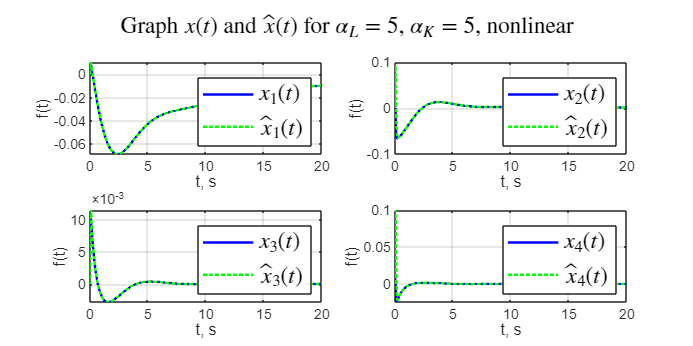

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\4_6_55e.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);



% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x_real(:,1), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat(:,1), 'g:', 'LineWidth',1.5); 
legend('$x_1(t)$', '$\hat{x}_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 70])
grid()
hold off

subplot(2,2,2);
plot(t, x_real(:,2), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat(:,2), 'g:', 'LineWidth',1.5); 
legend('$x_2(t)$','$\hat{x}_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 70])
grid()
hold off

subplot(2,2,3);
plot(t, x_real(:,3), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat(:,3), 'g:', 'LineWidth',1.5); 
legend('$x_3(t)$','$\hat{x}_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 70])
grid()
hold off

subplot(2,2,4);
plot(t, x_real(:,4), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat(:,4), 'g:', 'LineWidth',1.5); 
legend('$x_4(t)$','$\hat{x}_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 70])
grid()
hold off


sgtitle('Graph  $x(t)$ and $\hat{x}(t)$ for $\alpha_L = 5$, $\alpha_K=5$, nonlinear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\4_6_55x.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);
